va_path = 'va_data';
fileStruct =dir(fullfile(va_path, '*.csv'));

numFiles = length(fileStruct);
allData = cell(1, numFiles);



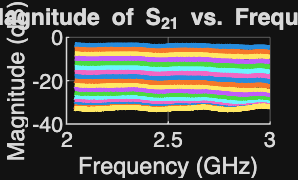

    figure; 
    hold on;
    gifFile = 'VAS21Plot.gif';
for i = 1:numFiles
    filePath = fullfile(va_path, fileStruct(i).name);
    data = readmatrix(filePath);
    allData{i} = data;
    % Column 1: Frequency in Hz
    % Column 2: Real part of S21
    % Column 3: Imaginary part of S21
    Freq_Hz = data(50:end, 1);
    S21_dB = data(50:end, 6);
    Im_S21_angle = data(50:end, 7);
    
    

   

    plot(Freq_Hz / 1e9, S21_dB, 'LineWidth', 2); 
    
    title('Magnitude of S_{21} vs. Frequency');
    xlabel('Frequency (GHz)');
    ylabel('Magnitude (dB)'); 
    grid on;
    drawnow;
    ylim([-40, 0]);
    exportgraphics(gcf, gifFile, 'Append', true);
        
end
hold off;

fprintf('done!');

done!

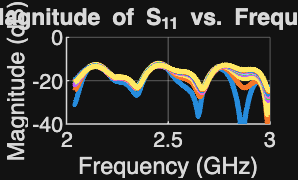

figure;
hold on;
gifFile = 'VAS11Plot.gif';
for i = 1:numFiles
    filePath = fullfile(va_path, fileStruct(i).name);
    data = readmatrix(filePath);
    allData{i} = data;
    % Column 1: Frequency in Hz
    % Column 2: Real part of S21
    % Column 3: Imaginary part of S21
    Freq_Hz = data(50:end, 1);
    S21_dB = data(50:end, 2);
    Im_S21_angle = data(50:end, 3);
    
    

    plot(Freq_Hz / 1e9, S21_dB, 'LineWidth', 2); 
    
    title('Magnitude of S_{11} vs. Frequency');
    xlabel('Frequency (GHz)');
    ylabel('Magnitude (dB)'); 
    grid on;
    drawnow;
    ylim([-40, 0]);
    exportgraphics(gcf, gifFile, 'Append', true);
        
end
hold off;

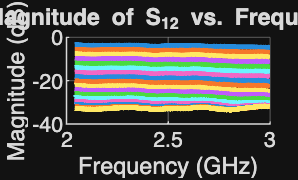


figure;
hold on;
gifFile = 'VAS12Plot.gif';
for i = 1:numFiles
    filePath = fullfile(va_path, fileStruct(i).name);
    data = readmatrix(filePath);
    allData{i} = data;
    % Column 1: Frequency in Hz
    % Column 2: Real part of S21
    % Column 3: Imaginary part of S21
    Freq_Hz = data(50:end, 1);
    S21_dB = data(50:end, 4);
    Im_S21_angle = data(50:end, 5);
    
    

    plot(Freq_Hz / 1e9, S21_dB, 'LineWidth', 2); 
    
    title('Magnitude of S_{12} vs. Frequency');
    xlabel('Frequency (GHz)');
    ylabel('Magnitude (dB)'); 
    grid on;
    drawnow;
    ylim([-40, 0]);
    exportgraphics(gcf, gifFile, 'Append', true);
        
end
hold off;

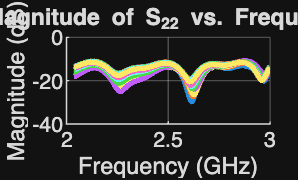


figure;
hold on;
gifFile = 'VAS22Plot.gif';
for i = 1:numFiles
    filePath = fullfile(va_path, fileStruct(i).name);
    data = readmatrix(filePath);
    allData{i} = data;
    % Column 1: Frequency in Hz
    % Column 2: Real part of S21
    % Column 3: Imaginary part of S21
    Freq_Hz = data(50:end, 1);
    S21_dB = data(50:end, 8);
    Im_S21_angle = data(50:end, 9);
    
    

    plot(Freq_Hz / 1e9, S21_dB, 'LineWidth', 2); 
    
    title('Magnitude of S_{22} vs. Frequency');
    xlabel('Frequency (GHz)');
    ylabel('Magnitude (dB)'); 
    grid on;
    drawnow;
    ylim([-40, 0]);
    exportgraphics(gcf, gifFile, 'Append', true);
        
end
hold off;